Mode number: 1
kx : 0.504
Error of calculation: 0.000
Power: 1.000


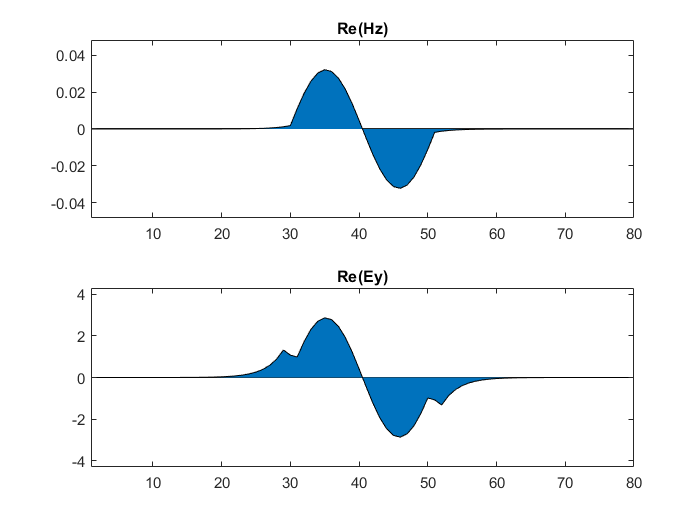

Mode number: 2
kx : 0.436
Error of calculation: 0.000
Power: 1.000


clear all;
close all;
clc

eps = ones([40 80]);
eps(:, 30:50) = 12.25;
eps(3 : end-2, 3 : end-2) = 9.0;

c = 3 * 10^8;
omega = 0.15 * c;

prob = form(omega, eps, [1 12.25], [1 2], 'pml', 'pos');

iter_num 	sub 	phy_res 	grad
      1: 	(x) 	5.000e-06 	1.591e-03
      1: 	(y) 	3.837e-06 	1.300e-03
      2: 	(x) 	3.127e-06 	1.181e-03
      2: 	(y) 	2.702e-06 	1.208e-03
      3: 	(x) 	2.380e-06 	1.139e-03
      3: 	(y) 	2.155e-06 	1.164e-03
      4: 	(x) 	1.983e-06 	1.115e-03
      4: 	(y) 	1.847e-06 	1.139e-03
      5: 	(x) 	1.736e-06 	1.097e-03
      5: 	(y) 	1.644e-06 	1.117e-03
      6: 	(x) 	1.568e-06 	1.079e-03
      6: 	(y) 	1.501e-06 	1.095e-03
      7: 	(x) 	1.443e-06 	1.062e-03
      7: 	(y) 	1.391e-06 	1.076e-03
      8: 	(x) 	1.345e-06 	1.045e-03
      8: 	(y) 	1.302e-06 	1.057e-03
      9: 	(x) 	1.263e-06 	1.027e-03
      9: 	(y) 	1.227e-06 	1.038e-03
     10: 	(x) 	1.194e-06 	1.009e-03
     10: 	(y) 	1.162e-06 	1.018e-03
     11: 	(x) 	1.134e-06 	9.915e-04
     11: 	(y) 	1.106e-06 	1.000e-03
     12: 	(x) 	1.081e-06 	9.743e-04
     12: 	(y) 	1.057e-06 	9.831e-04
     13: 	(x) 	1.035e-06 	9.577e-04
     13: 	(y) 	1.014e-06 	9.665e-04
     14: 	(x) 	9.936e-07 	9.418e-04

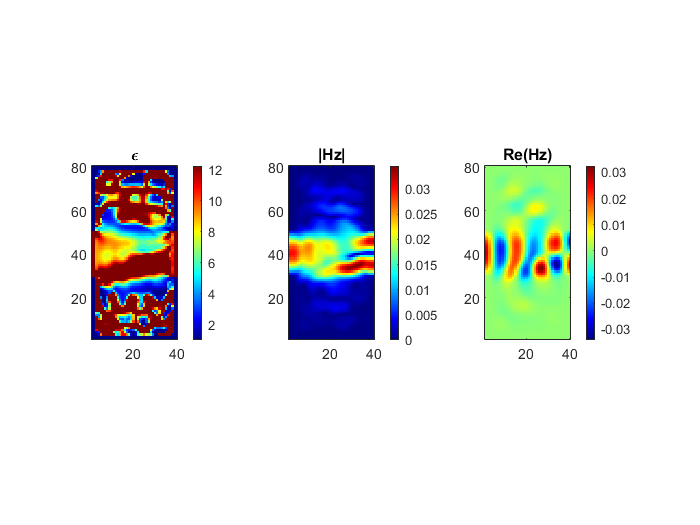

50 iterations completed in 84.5 second.


eps = optimize(prob, 50, 1e-4);

Input mode analysis
 Mean total power: 0.96
 Error: 0.00
 Mean mode power: 0.96
 Error: 0.00
 Ratio: 1.00
 
Output mode analysis
 Mean total power: 0.92
 Error: 0.00
 Mean mode power: 0.86
 Error: 0.00
 Ratio: 0.94
 
Conversion effeciency: 0.90

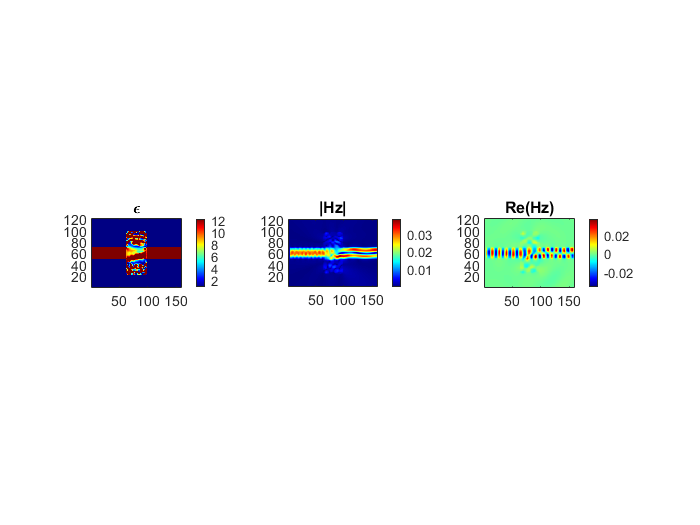

thick = [60, 60, 20, 20];
[Ex, Ey, Hz] = simulate(eps, thick, prob);

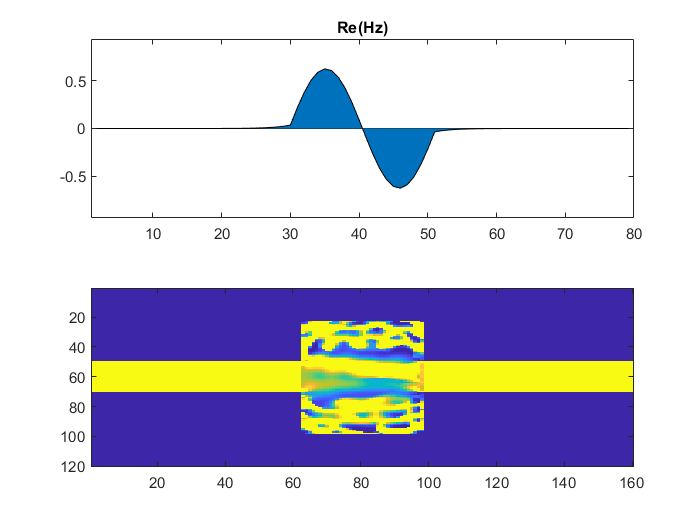

% export the eps
fileID = fopen('eps_f.txt', 'w+')

[y, x, eps_f] = find(eps');
y = 120 - y;
result = [x'; y'; eps_f'];

fprintf(fileID, '%e %e %e\n', result);
fclose(fileID);

% check the output result
fileID = fopen('eps_f.txt', 'r');
A = fscanf(fileID, '%e %e %e', [3, inf]);
A = A';
eps = reshape(A(:, 3), [120 + 40, 160 + 40]);
imagesc(eps)